% - - - - - - - - TERNARY U-N-O PHASE STABILITY PLOTS - - - - - - - - 

%     _______                                 _____  _                      _____  _                                    _____                           _             
%    |__   __|                               |  __ \| |                    |  __ \(_)                                  / ____|                         | |            
%       | | ___ _ __ _ __   __ _ _ __ _   _  | |__) | |__   __ _ ___  ___  | |  | |_  __ _  __ _ _ __ __ _ _ __ ___   | |  __  ___ _ __   ___ _ __ __ _| |_ ___  _ __ 
%       | |/ _ \ '__| '_ \ / _` | '__| | | | |  ___/| '_ \ / _` / __|/ _ \ | |  | | |/ _` |/ _` | '__/ _` | '_ ` _ \  | | |_ |/ _ \ '_ \ / _ \ '__/ _` | __/ _ \| '__|
%       | |  __/ |  | | | | (_| | |  | |_| | | |    | | | | (_| \__ \  __/ | |__| | | (_| | (_| | | | (_| | | | | | | | |__| |  __/ | | |  __/ | | (_| | || (_) | |   
%       |_|\___|_|  |_| |_|\__,_|_|   \__, | |_|    |_| |_|\__,_|___/\___| |_____/|_|\__,_|\__, |_|  \__,_|_| |_| |_|  \_____|\___|_| |_|\___|_|  \__,_|\__\___/|_|   
%                                      __/ |                                                __/ |                                                                     
%                                     |___/                                                |___/                                                                      

% ! ! ! ! ! ! ! SUSPECTED ISSUES ! ! ! ! ! ! ! 
% I am gtting some results with teh wrong number of atoms!
% this is probably form move of binary -> ternary and there are duplicate
% entries for the right and wrong num of atoms.
% howecer we still get the same predicted Ef


%global metal 
%metal = 'U';

tic
% importing data - - - - - - - - -
training_data = readtable("targets_extra-cols.csv");    % data used to train the models
nn_data = readtable("data_ternaryUNO-NN.csv");          % Neural Network Predictions
nn_data = unique([nn_data(:,"formula"),nn_data(:,"Ef")]);       % triming down unnescesary cols cols and removing dupe rows
rf_data = readtable("data_ternaryUNO-RF.csv");          % Random Forrest Predictions
rf_data = unique([rf_data(:,"formula"),rf_data(:,"Ef")]);
nnrf_data = readtable("data_ternaryUNO-NNRF.csv");        % Ensemble model Predictions (NN & RF)
nnrf_data = unique([nnrf_data(:,"formula"),nnrf_data(:,"Ef")]);

nn_data(103:105,:)

ans = 3×2 table
     formula             Ef         
    _________    ___________________

    {'UN3O4'}     -0.445664257319658
    {'UN4'  }    -0.0228905138546232
    {'UN4'  }     -0.022890513854623


nnrf_data(103:105,:)

ans = 3×2 table
     formula             Ef        
    _________    __________________

    {'UN3O4'}     -1.10858460114698
    {'UN4'  }    -0.170491634211899
    {'UN4'  }    -0.170491634211899



nn_data(105,:) = []; %for some reason unique was not removing duplicates (UN4) so done manually
nnrf_data(105,:) = []; %for some reason unique was not removing duplicates (UN4) so done manually

% paring down training data to points relevent to UN,UO or UNO (in either order) only - - - - - -- 
uno_training = table();
j = 1;
for i = 1:height(training_data)
    str = regexprep(char(training_data{i,"formula"}), '\d', ''); 
    %str = str(~ismember(str,'()')); % there is no pure 
    if strcmp(str,'UNO') | strcmp(str,'UON') | strcmp(str,'UN') | strcmp(str,'UO') % if we remove numbers (as done above) all UxNy will be displayed as "UN"
        uno_training(j,:) = training_data(i,:);
        j = j+1;
    end
end

%uno_training = table();     will eventually check that there are no Ux(NyOz)m in training data
%j = 1;
%for i = 1:height(training_data)
%    str = char(training_data{i,"formula"});
%    %str = str(~ismember(str,'()')); % there is no pure 
%    if strcmp(str,'U')  % if we remove numbers (as done above) all UxNy will be displayed as "UN"
%        uno_training(j,:) = training_data(i,:);
%        j = j+1;
%    end
%end

clear training_data j str 
toc

Elapsed time is 3.575326 seconds.


tic
train_ofracs = zeros(height(uno_training),2);
for i = 1:height(uno_training)
    train_ofracs(i,:) = oxidant_fractions(uno_training{i,"formula"},['N','O']);
end
nn_ofracs = zeros(height(nn_data),2);
for i = 1:height(nn_data)
    nn_ofracs(i,:) = oxidant_fractions(nn_data{i,"formula"},['N','O']);
end
rf_ofracs = zeros(height(rf_data),2);
for i = 1:height(rf_data)
    rf_ofracs(i,:) = oxidant_fractions(rf_data{i,"formula"},['N','O']);
end
nnrf_ofracs = zeros(height(nnrf_data),2);
for i = 1:height(nnrf_data)
    nnrf_ofracs(i,:) = oxidant_fractions(nnrf_data{i,"formula"},['N','O']);
end

toc

Elapsed time is 0.255259 seconds.


% - - - - - - - - reformatting to aid plotting - - - - - - - - 
pure_U_entry = table(0,0,0,VariableNames={'nfrac','ofrac','Ef_eV'}, RowNames={'U'});
pure_N_entry = table(1,0,0,VariableNames={'nfrac','ofrac','Ef_eV'}, RowNames={'N'});
pure_O_entry = table(0,1,0,VariableNames={'nfrac','ofrac','Ef_eV'}, RowNames={'O'});
NO_virual_node = table(1,1,0,VariableNames={'nfrac','ofrac','Ef_eV'}, RowNames={'NO virt'});

% - - - UNO training data - - - 
train_post = table(train_ofracs(:,1),train_ofracs(:,2),uno_training{:,"Ef"},... % UxNy Training data
             VariableNames={'nfrac','ofrac','Ef_eV'},...
             RowNames=uno_training{:,"formula"});
train_post = vertcat(train_post,pure_U_entry,pure_N_entry,pure_O_entry,NO_virual_node);

% - - - NN data - - - 
nn_post = table(nn_ofracs(:,1),nn_ofracs(:,2),nn_data{:,"Ef"},... % UxNy Training data
             VariableNames={'nfrac','ofrac','Ef_eV'},...
             RowNames=nn_data{:,"formula"});
nn_post = vertcat(nn_post,pure_U_entry,pure_N_entry,pure_O_entry,NO_virual_node);
% - - - RF data - - - 
rf_post = table(rf_ofracs(:,1),rf_ofracs(:,2),rf_data{:,"Ef"},... % UxNy Training data
             VariableNames={'nfrac','ofrac','Ef_eV'},...
             RowNames=rf_data{:,"formula"});
rf_post = vertcat(rf_post,pure_U_entry,pure_N_entry,pure_O_entry,NO_virual_node);
% - - - NNRF data - - - 
nnrf_post = table(nnrf_ofracs(:,1),nnrf_ofracs(:,2),nnrf_data{:,"Ef"},... % UxNy Training data
             VariableNames={'nfrac','ofrac','Ef_eV'},...
             RowNames=nnrf_data{:,"formula"});
nnrf_post = vertcat(nnrf_post,pure_U_entry,pure_N_entry,pure_O_entry,NO_virual_node);

%train_post = sortrows(train_post,"oxidant_fraction","ascend"); % not
%ordering data (yet?)

Neural Network: 17 stable phases have been identified (Ef ascending):
                     Ef_eV       
               __________________

    UO2          -3.8192987939272
    UNO         -2.44346775874878
    U2O19       -2.43653410421165
    UO10        -2.41060163529589
    UO11        -2.35874091366294
    UO12        -2.31355346836687
    UO28        -2.00209005839662
    U2N3         -1.5127065652061
    UN2           -1.495191535229
    U2N3O17     -1.48064764242649
    U4N5        -1.47879773831711
    UN          -1.41583815017175
    UN21       -0.337641131204135
    N                           0
    U                           0
    O                           0
    

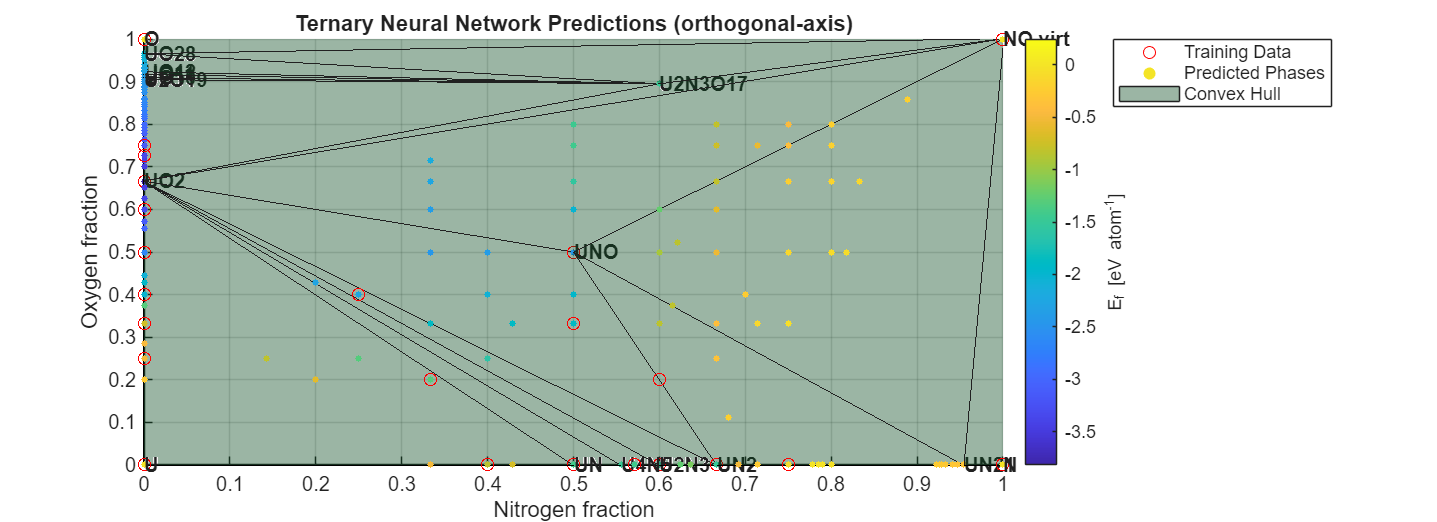

ternary_plot('Neural Network',nn_post,train_post,1)

No new nodes to find, 4 stable phases found
Random Forrest: 15 stable phases have been identified (Ef ascending):
                      Ef_eV       
                __________________

    UO2           -3.8192987939272
    UO28         -2.68346612173728
    UNO          -2.44346775874878
    U2N3O17      -2.03217715397829
    U2N3          -1.5127065652061
    UN2            -1.495191535229
    U(N3O)4      -1.42715634875806
    U(N4O3)2      -1.4247765927233
    UN           -1.41583815017175
    UN6O         -1.40799515100765
    UN21        -0.595715781183339
    N                            0
    U                            0
    O                            0
    NO virt                      0



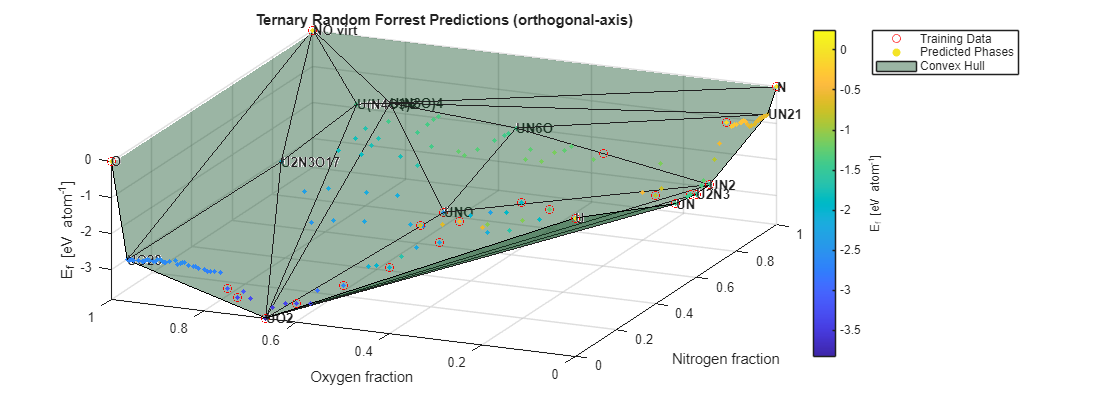


ternary_plot('Random Forrest',rf_post,train_post,0)

No new nodes to find, 6 stable phases found
Ensemble Learning: 13 stable phases have been identified (Ef ascending):
                      Ef_eV       
                __________________

    UO2           -3.8192987939272
    UNO          -2.44346775874878
    UO28         -2.34277809006695
    U2N3O17      -1.75641239820239
    U2N3          -1.5127065652061
    UN2            -1.495191535229
    UN           -1.41583815017175
    U(N4O3)2    -0.818407983482177
    UN21        -0.466678456193737
    N                            0
    U                            0
    O                            0
    NO virt                      0



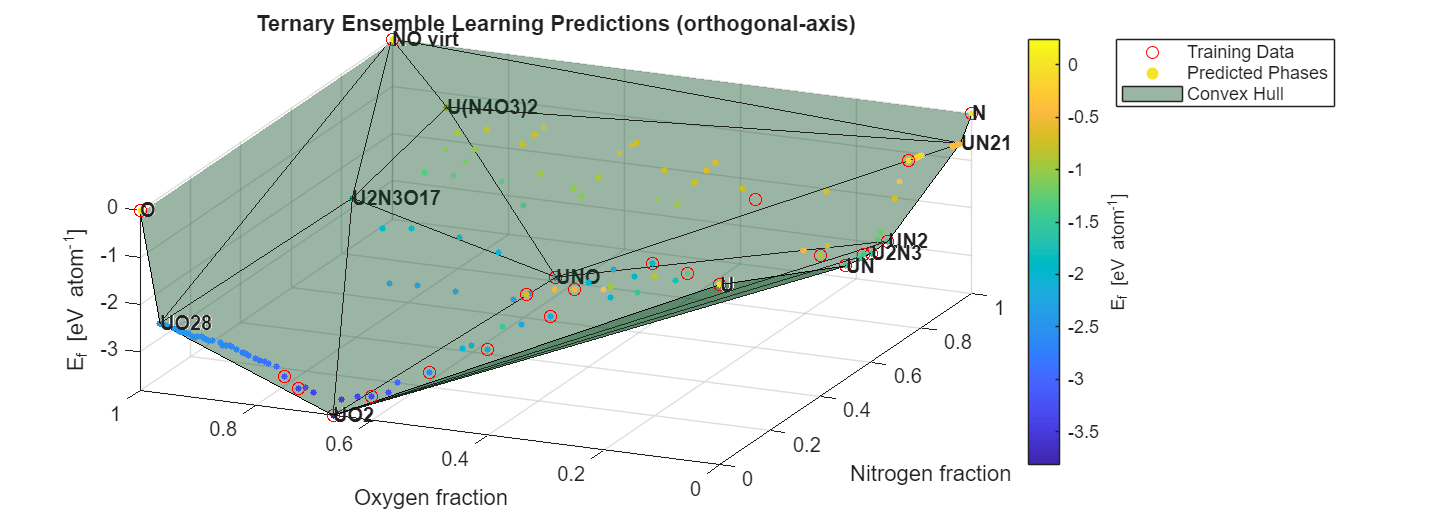


ternary_plot('Ensemble Learning',nnrf_post,train_post,0)

% - - - - - - - - - - - - - - - - - - - - - Relevent functions to script - - - - - - - - - - - - - - - - - - - - - 

function ternary_plot(learning_type,T,training,ifrot)
    %T
    x = T{:,"nfrac"};
    y = T{:,"ofrac"};
    z = T{:,"Ef_eV"};
    
    % - - - stable phase identification - - - 
    % in 2d along edges descpite finding the convex hull we stil need to note
    % the phases that are stable as the convex hull misidentifies some unstable
    % phases as stable at the oxidant-fraction = 0 planes.
    
    T_oxygen = T;
    T_oxygen(contains(T.Properties.RowNames, 'N'), :) = [];
    T_oxygen = sortrows(T_oxygen,"ofrac","ascend");
    [o_pl, stable_phasesO] = binary_stable_phase_identification(T_oxygen{:,"ofrac"},T_oxygen{:,"Ef_eV"});
    binaryO_stableP = T_oxygen(stable_phasesO,:);
    T_nitrogen = T;
    T_nitrogen(contains(T.Properties.RowNames, 'O'), :) = [];
    T_nitrogen = sortrows(T_nitrogen,"nfrac","ascend");
    [n_pl, stable_phasesN] = binary_stable_phase_identification(T_nitrogen{:,"nfrac"},T_nitrogen{:,"Ef_eV"});
    binaryN_stableP = T_nitrogen(stable_phasesN,:);
    binaryN_stableP("U",:) = []; %remove dupelicate U entry
    
    [ch,~] = convhull(x,y,z);
    
    ternaryStablePhases = T(unique(ch(:)),:); % selects all positions identified by the convex hull
    ternaryStablePhases(ternaryStablePhases.ofrac==0,:) = []; % removes rows with only UxNy
    ternaryStablePhases(ternaryStablePhases.nfrac==0,:) = []; % removes all UxOy
    
    stable_phases = sortrows(vertcat(binaryN_stableP,binaryO_stableP,ternaryStablePhases),3,"ascend");
    clear binaryO_stableP binaryO_stableP ternaryStablePhases
    disp([learning_type,': ',num2str(height(stable_phases)),' stable phases have been identified (Ef ascending):'])
    disp(stable_phases(:,"Ef_eV"))

    % - - - - - - plotting - - - - - - - 
    f = figure;
    f.Position = [100, 100, 1100, 400];
    scatter3(training{:,1},training{:,2},training{:,3},'or')
    hold on
    scatter3(x,y,z,10,z,"filled")
    %c = parula(height(z));
    cd = colorbar();
    cd.Label.String = 'E_f [eV atom^-^1]';
    
    modz = z+0.001;
    mody = y;
    modx = x;
    for i = 1:length(y)
        if mody(i) == 1
            mody(i) = 1.001;
        elseif mody(i) == 0
            mody(i) = -0.001;
        end

        if modx(i) == 1
            modx(i) = 1.001;
        elseif modx(i) == 0
            modx(i) = -0.001;
        end
    end
    ts = trisurf(ch,modx,mody,modz,'FaceColor','cyan');
    ts.FaceColor = '#04471C';
    ts.FaceAlpha = 0.4;

    plot3(zeros(size(o_pl)), T_oxygen{:,"ofrac"},o_pl, 'k')
    plot3(T_nitrogen{:,"nfrac"}, zeros(size(n_pl)), n_pl, 'k')

    for i = 1:height(stable_phases)
        text(stable_phases{i,"nfrac"}, ...
            stable_phases{i,"ofrac"},...
            stable_phases{i,"Ef_eV"}, ...
            stable_phases.Properties.RowNames{i},...
            "FontWeight","bold")
    end

    xlabel('Nitrogen fraction')
    ylabel('Oxygen fraction')
    zlabel('E_f [eV atom^-^1]')
    title(['Ternary ',learning_type,' Predictions (orthogonal-axis)'])
    legend({'Training Data','Predicted Phases','Convex Hull'})
    xlim([0 1])
    ylim([0 1])
    zlim([min(T.Ef_eV) 0])

    if ifrot == 1
        for angle = 1:360
            % Update the view angle. Azimuth (horizontal) changes, elevation stays fixed.
            view([angle, 30]);
            % Update the figure display immediately
            drawnow;
            % Optional: Add a pause to control speed
            pause(0.01);
        end
        view([0.00 90.00])
    else
        view([-66.5 46])
        %maybe add text adjustment here
    end
    
    hold off
end

function [y_pl, stable_phases] = binary_stable_phase_identification(frac,ef)
    % function that generates the piecewise linear line between stable
    % phases and identifies what phases are stable (to plot afterwards)

    %x = T{:,"oxidant_fraction"};
    %y = T{:,"Ef_eV"};

    % Stable Phase Identification 
    
    residual = ef;
    nodes = [1,length(frac)]; % starting with nodes at the stable pure phases (labeled as array indexes)
    
    halt = 0;
    while halt == 0
        % loop over our new node generation untill there are no new nodes required
        % to bound our formation energies from below with piecewise liniarity     
        [residual, nodes, halt] = node_identification_binary(frac,residual,nodes);
    end
    %stable_phases = ismember(residual,0); 
    % used to calculate off of i the residual was 0 but floating point 
    % error got in the way, just using node positions, far simpler
    stable_phases = nodes;
    
    %[stable_phases,y_pl,y]
    
    % the piecewise linear plot is the diference between our residual and our unaltered data
    y_pl = ef - residual;
end

function [residual, nodes, halt_condition] = node_identification_binary(x,y,nodes)
    % this function is used iterativly. When given the dataset of Ef wrt to
    % phase, it will identify the global minimum and partition it into 2 PL
    % segments. Further iterations will find points below the residual and 
    % generate a new node. This is repeted untill there are no phases below
    % our PL curve.
    % original residual is wrt PL between pure phases.

    % if points below our current line we need an aditional node to
    % describe this stable phase 
    
     
    [~, node] = min(y);
    %disp(x(node))
    if ismember(node, nodes)
        halt_condition = 1;
        residual = y;
        return;
    end
    nodes = [nodes,node];
    nodes = sort(nodes);

    [~, node_idx] = min(abs(nodes - node));
    nodeLHS = nodes(node_idx-1); % left neighbour
    nodeRHS = nodes(node_idx+1); % right neighbour

    % find line connecting neighboring nodes to this new one
    % generating peicwise linearity with y = m x - m*xNode + yNode. Where: m = (yNeibour - yNode) / (xNeibour - xNode) 
    % xI and yI are node coordinates in Ef eV/atom and nitrogen fraction.
    y_plLHS = ((y(nodeLHS) - y(node)) / (x(nodeLHS) - x(node))).*x ...   % peicewise linearity new node and LHS node neighbour
             -((y(nodeLHS) - y(node)) / (x(nodeLHS) - x(node)))*x(node) + y(node);
    y_plRHS = ((y(nodeRHS) - y(node)) / (x(nodeRHS) - x(node))).*x ...   % peicewise linearity new node and RHS node neighbour
             -((y(nodeRHS) - y(node)) / (x(nodeRHS) - x(node)))*x(node) + y(node);
    y_pl = vertcat(y_plLHS(1:node),y_plRHS(node+1:end));
    %( (y(nodeLHS) - y(node) ) / ( x(nodeLHS) - x(node) ) )
    %((y(nodeRHS) - y(node)) / (x(nodeRHS) - x(node)))

    residual = y;
    residual(nodeLHS:nodeRHS) = residual(nodeLHS:nodeRHS) - y_pl((nodeLHS:nodeRHS));
    %disp(['Stable Nodes [oxidant-fraction]:    ',num2str(x(nodes).')])
    
    % checking if another iteration will be required.
    newnode_val = min(residual);
    if newnode_val >= 0
        halt_condition = 1;
        disp(['No new nodes to find, ', num2str(length(nodes)),' stable phases found'])
        nodes = unique(nodes); % otehrwise numerical error can cause double counting 
    else
        halt_condition = 0;
    end
    
end

function stoich = get_stoichiometry(formula,element)
    % searches for all consecutive digits after a given starting point and
    % returns the number ie reads U1234NO as 1234. if told to look for 'U'
    % in the character array.
    element_idx = strfind(formula,element);
    formula = [formula(element_idx+1:end),'|'];     % only considering the relevent part of the formula and adding a stopper to the end "|" so we never have an empty string
    i = 1;
    stoich = 0;
    %disp(['is ',formula(i),' a digit?: ',num2str(~isnan(str2double(formula(i))))])
    if isnan(str2double(formula(i))) && ~isempty(element_idx) % logical if the i-th char in the string is NOT a digit 
        %disp('No subsequent digits')
        stoich = 1;            % if no number follows our element then stoich is 1 (AB2 = A1B2)
    elseif ~isnan(str2double(formula(i)))
        %disp('∃ subsequent digits')
        while ~isnan(str2double(formula(i)))
            stoich = stoich + 10^(1-i)*str2double(formula(i)); % appending new digit 1 dp lower than last
            i = i+1;    % incrementing counter
        end
        stoich = stoich*10^(i-2); % multiplying up by 10 ^ (number of digits appended)
        %disp(stoich)
    end
    % as we can have formulae of the form Ux(IyJz)n we need to check for
    % brackets and retun stoich of y*n and z*n
    
    open_bracket = strfind(formula,'(');
    close_bracket = strfind(formula,')');
    if isempty(open_bracket) && ~isempty(close_bracket) % as we remove  char before our element if open bracket is missing then we are in the brackets
        stoich = stoich * str2double(formula(close_bracket+1:end-1)); % only works with assumption that the last item is our brackets and we have only 1 set of brackets
    end

end

function oxfracs = oxidant_fractions(formula,oxidants)
    % - - - - - oxidant fractions - - - - - - - HARDCODED FOR TERNARY UxIyJz
    % we now have formulae of the form - UxIyJz or Ux(IyJz)n where I & J are
    % our oxidants (U and N), we can now have groups in our solid (in brackets)
    % with their own stoichiometry, to develop fractions we will need to regen
    % a machine readable version of the formula with UxI(y*n)J(z*n) parallel to
    % the formulae array to read oxidant fractions, note we will have
    % orthogonal fractions for I and J (I = N, J = O in majority of cases)
    formula = char(formula);
    
    stoich = zeros(3,1);
    stoich(1) = get_stoichiometry(formula,'U');           % number of U in formula
    stoich(2) = get_stoichiometry(formula,oxidants(1));   % number of N in formula
    stoich(3) = get_stoichiometry(formula,oxidants(2));   % number of O in formula
    
    % we will now construct 2 orthogonal axis that describe I fraction and J
    % fraction eg with U(NO2)2 we would have 2/3 and 4/5 respectivly 
    oxfracs(1) = stoich(2)/(stoich(2)+stoich(1));
    oxfracs(2) = stoich(3)/(stoich(3)+stoich(1));
end













%{
% Ternary Phase Diagram Example
% Author: [Your Name]
% Date: 2025-11-10

% -----------------------------
% Example data: compositions in %
% Each row: [ComponentA, ComponentB, ComponentC]
% Sum of each row should be 100
% -----------------------------
data = [
    70 20 10;
    60 30 10;
    50 30 20;
    40 40 20;
    30 50 20;
    20 60 20
];

% Validate data
if any(abs(sum(data, 2) - 100) > 1e-6)
    error('Each composition must sum to 100.');
end

% Convert ternary (A,B,C) to Cartesian (x,y)
% Equilateral triangle with side length = 1
A = data(:,1) / 100;
B = data(:,2) / 100;
C = data(:,3) / 100;

% Cartesian conversion
x = 0.5 * (2*B + C) ./ (A + B + C);
y = (sqrt(3)/2) * C ./ (A + B + C);

% Plot triangle boundary
figure;
hold on; axis equal; axis off;
plot([0 1 0.5 0], [0 0 sqrt(3)/2 0], 'k-', 'LineWidth', 1.5);

% Plot data points
scatter(x, y, 80, 'filled', 'MarkerFaceColor', 'r');

% Label corners
text(-0.05, -0.05, 'A', 'FontWeight', 'bold', 'FontSize', 12);
text(1.05, -0.05, 'B', 'FontWeight', 'bold', 'FontSize', 12);
text(0.5, sqrt(3)/2 + 0.05, 'C', 'FontWeight', 'bold', 'FontSize', 12);

title('Ternary Phase Diagram', 'FontSize', 14);

% Optional: grid lines
nGrid = 5;
for i = 1:nGrid-1
    % Parallel to AB
    plot([i/nGrid, 0.5 + (i/(2*nGrid))], ...
         [sqrt(3)/2*(1 - i/nGrid), sqrt(3)/2*(1 - i/nGrid)], ...
         'Color', [0.8 0.8 0.8]);
end

hold off;
%}


%{

manual convex hull attempt

% - - - - - - - - - Stable plane workings - - - - - - - - - - -

% have to consider the stable planes
% similarly we have fixed nodes at our 1 and 0 frac points, but for this we
% need to order our data such that the notes can be mirrored to the actual
% Ef minema.


%{
- - - - - - - - - - - - - - node matrix layout - - - - - - - - - - - - - - - -

                       x

        U    .    .    UN   .    .    N
        .    .    .    .    .    .    .      DIFFERENT ROTATION TO SCATTER ABOVE
        .    .    .    .    .    .    .
   y    UO   .    .    .    .    .    .      <-  2d matrix    
        .    .    .    .    .    .    .          2 layers deep (3d) 
        .    .    .    .    .    .    .          layer 1 = nodes, layer 2 = Ef values
        O    .    .    .    .    .    . 


- - - - - - - - - - - - - - plane generation - - - - - - - - - - - - - - - - - 
%need to define pl between all nodes such that we are only prtitioning a
%plane that the point lies in

* = old nodes ,   @ = new node   [ / | - ] = old partition   x = new partition    plares are numbered

                                6
    Ef          *----------*---------------------*   ->  Nitrogen (x)
    out of      |         /  \  x       3      x |
    page        |        /     \     x       x   |
                |   1   /        \        @      |
                |      /     2     \   4   x  5  |
                |     /              \      x    |      we see plane one is uneffected by the new node (O) and partitions (x)
                |    /                 \     x   |      Not the best diagram but see work for more
                |   /                    \    x  |
                |  /                       \   x |    
                | /                           \ x|
                *--------------------------------*
                
                |
                v Oxygen (y)

so the software must recognise what plane the new node lies in.

 - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - -
%}



ux = unique(x); % nitrogen
uy = unique(y);


% x and y are flipped if we map x to col and y to row
node_matrix = zeros(length(uy),length(ux),2);
% node_matrix(:,:,1) = nodes  &  node_matrix(:,:,2) = residual/Ef

for i = 1:height(T)
    [~, ux_pos] = min(abs(ux - x(i)));
    [~, uy_pos] = min(abs(uy - y(i)));
    if z(i) <= node_matrix(uy_pos,ux_pos,2)
        node_matrix(uy_pos,ux_pos,2) = z(i);
    end
end
[UX,UY] = meshgrid(ux,uy);
h=surf(UX,UY,node_matrix(:,:,2));
hold on
h.FaceColor = "none";
Zarray = node_matrix(:,:,2);
scatter3(UX(:),UY(:),Zarray(:),25,Zarray(:),"filled") % doesnt work
c = nebula(height(Zarray(:)));
cd = colorbar('colormap',c);
colormap(nebula);
title('node matrix mapped to formation enthalpy')
xlabel('Nitrogen')
ylabel('Oxygen')
zlim([min(node_matrix(:,:,2),[],"all") 0-0.01])
view([0 -90])
hold off
uxstr = arrayfun(@num2str, ux, 'UniformOutput', 0);
uystr = arrayfun(@num2str, uy, 'UniformOutput', 0);
ef_table = array2table(node_matrix(:,:,2));
ef_table.Properties.VariableNames = uxstr;    % not strictly nesecary but makes viewing easier
ef_table.Properties.RowNames = uystr;
%ef_table

% - - trivial nodes - -
node_matrix(1,1,1) = 1;
node_matrix(1,end,1) = 1;
node_matrix(end,1,1) = 1;
node_matrix(end,end,1) = 1; % this is a pseudonode, not well defined with our orthagonal axis 

% node identification
[min_of_each_row,row_node_idx] = min(node_matrix(:,:,2));
[~, col_node_idx] = min(min_of_each_row);
row_node_idx = row_node_idx(col_node_idx);

% minimum is the new node in the array
%node_matrix(:,:,1)
%node_matrix(:,:,2)
%node_matrix(row_node_idx,col_node_idx,2) - min_of_each_row(col_node_idx)
node_matrix(row_node_idx,col_node_idx,1) = 1;

% defining planes
% as we start with 4 points describing 1 place (2 sets of mutually
% orthogonal colinear lines) the addition of the first node is a special
% case.
%}
